# [**k-Nearest Neighbors Classifier**](https://apmonitor.com/pds/index.php/Main/KNearestNeighbors)

## Introduction 

Neighbors based classification is a type of lazy learning as it does not attempt to construct a general internal model, but simply stores instances of the training data. Classification is computed from a simple majority vote of the k-nearest neighbors of each point. Specifically, k-Nearest Neighbors (kNN) is a type of instance-based learning or non-parametric learning algorithm, where the model is not explicitly trained, but instead makes predictions by comparing new data points to the nearest neighbors in the training data. The algorithm works by calculating the distances between the new data point and the training data, selecting the k-nearest data points, and then making a prediction based on the class or label of the selected neighbors.

**Advantages:** This algorithm is simple to implement, robust to noisy training data, and effective if training data is large.

**Disadvantages:** The value of *k* needs to be determined, and the computational cost is high because the distance from each instance to all training samples needs to be calculated. A feedback loop can be used to determine the optimal number of neighbors to use in the prediction. 

**k-Nearest Neighbors in MATLAB**

Here is an example of k-nearest neighbors in MATLAB using test and training data. 

% Load the data
load fisheriris
X_fish = meas(:, 3:4);
Y_fish = species;

% Split the data into training and testing sets
idx = randperm(size(X_fish, 1));
X_train = X_fish(idx(1:100), :);
Y_train = Y_fish(idx(1:100));
X_test = X_fish(idx(101:end), :);
Y_test = Y_fish(idx(101:end));

% Create a k-nearest neighbors classifier with 3 neighbors
model = fitcknn(X_train, Y_train, 'NumNeighbors', 3);

% Make predictions on the test set
y_pred = predict(model, X_test);

% Convert the cell array of strings to a string array
y_pred_str = string(y_pred);
y_test_str = string(Y_test);

% Calculate the accuracy of the prediction
accuracy = (y_pred_str == y_test_str);
accuracy = (sum(accuracy)/length(accuracy))*100;
fprintf('Accuracy: %.1f%%', accuracy)

Accuracy: 90.0%

In this example, we first create a k-nearest neighbors classifier with 3 neighbors using the [fitcknn](https://www.mathworks.com/help/stats/fitcknn.html) function. Next the trained model makes predictions on the test set using the [*predict*](https://www.mathworks.com/help/stats/linearmodel.predict.html) function. The number of neighbors is the hyperparameter for tuning the performance. Change *n_neighbors* to a higher number to gain more consensus for the classification.

Here is an example that uses 5 nearest neighbors instead of 3. 

% Create a k-nearest neighbors classifier with 5 neighbors
model = fitcknn(X_train, Y_train, NumNeighbors=5);

% Make predictions on the test set
y_pred_5 = predict(model, X_test);

% Convert the cell array of strings to a string array
y_pred_str = string(y_pred);
y_test_str = string(Y_test);

% Calculate the accuracy of the prediction
accuracy = (y_pred_str == y_test_str);
accuracy = (sum(accuracy)/length(accuracy))*100;
fprintf('Accuracy: %.1f%%', accuracy)

Accuracy: 90.0%

The classifier atttained a high accuracy when using both 3 and 5 nearest neighbors to make a prediction. 

## **Optical Character Recognition with k-Nearest Neighbors**

Optical character recognition (OCR) is the process of extracting text from images or scanned documents. OCR algorithms are typically based on machine learning models trained with large datasets of images that contain text.

Here is an example of OCR using a k-nearest neighbors (kNN) classifier:

% Load in the ex4data for usage
load('ex4data1.mat');

% Split data 75-25
cv = cvpartition(size(X,1),'HoldOut',0.25);
idx = cv.test;

% Separate to training and test data
X_train_ocr = X(~idx,:);
Y_train_ocr = y(~idx,:);
X_test_ocr = X(idx,:);
Y_test_ocr = y(idx,:);

% Create a k-nearest neighbors classifier with 3 neighbors
model = fitcknn(X_train_ocr, Y_train_ocr, NumNeighbors=3);

% Make predictions on the test set
y_pred = predict(model, X_test_ocr);

% Compare Predictions to actual values 
predictions = y_pred == Y_test_ocr;

% Divide predictions by number of total predicitions
accuracy = (sum(predictions)/numel(Y_test_ocr))*100;
fprintf('Accuracy: %.1f%%', accuracy)

Accuracy: 93.8%

In this example, we first load the digits dataset from ex4data1.mat, which contains images of handwritten digits. Then, we create a k-nearest neighbors classifier, which uses 3 neighbors, with the fitcknn function. Next, we train the model on the the train dataset we developed. Finally, we use the trained model to make predictions on new images, and calculate accuracy by comparing the predicted values to the actual values, summing the accurate values and dividing this by total number of observations.

## **Activities**

**k-Nearest Neighbors for Animal Classification**

It is proposed to classify cats and dogs by weight. A total of 16 animals are measured and the data is split into a test (3) and train (13) set.

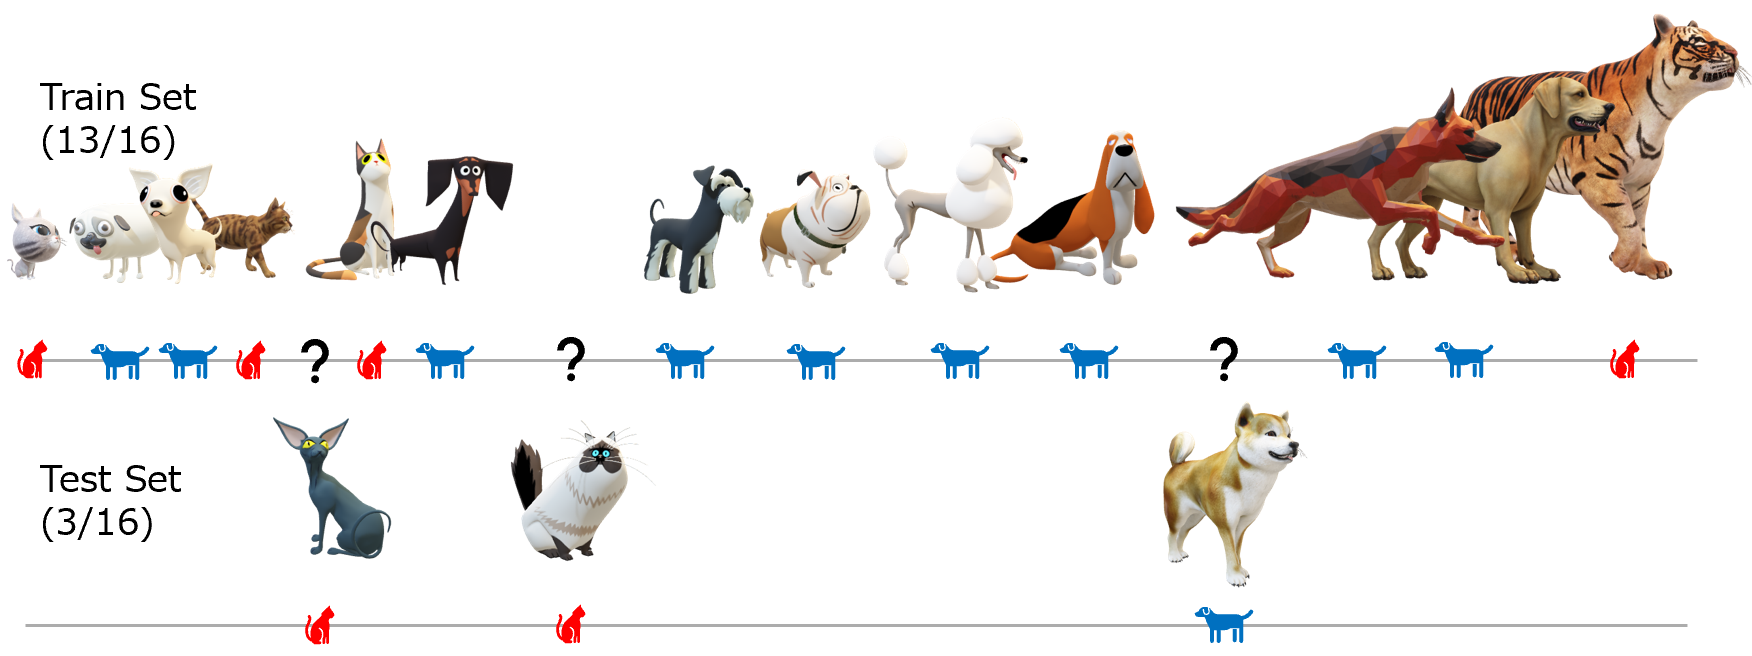

The accuracy of the classifier is defined as the number of correct test classifications divided by the total number in the test set.

Accuracy=(Correct / Total) * 100%

What is the accuracy of the dog and cat classifier with *k=2*?

**k-Nearest Neighbors Programmming**

Using only MATLAB code (not fitcknn() function), create a k-Nearest Neighbors classifier. Compare results with actual values and calculate accuracy to evaluate the performance of the code.

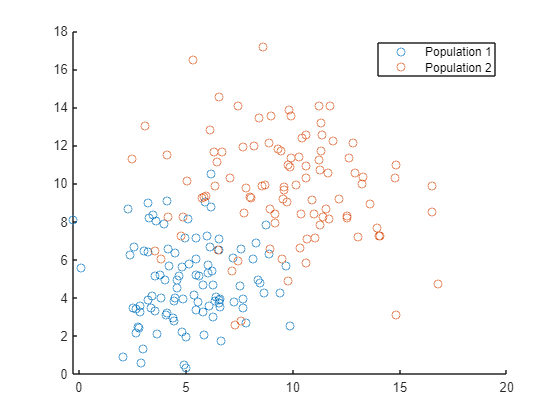

% Define parameters for population 1
mean_1 = 5;
std_1 = 2;

% Generate data for population 1, including labels
pop_1 = mean_1 + std_1 * randn(100, 2);
pop_1_label = ones(100,1);
pop1 = cat(2,pop_1,pop_1_label);

% Define parameters for population 2
mean_2 = 10;
std_2 = 3;

% Generate data for population 2, including labels
pop_2 = mean_2 + std_2 * randn(100, 2);
pop_2_label = 2*ones(100,1);
pop2 = cat(2,pop_2,pop_2_label);

% Plot the data
figure;
scatter(pop_1(:,1),pop_1(:,2));
hold on;
scatter(pop_2(:,1),pop_2(:,2));
legend('Population 1', 'Population 2');

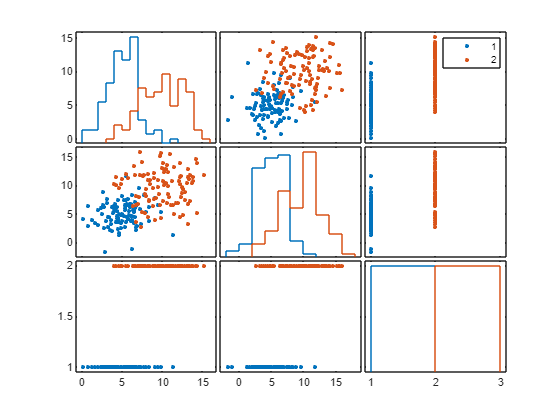


% Join the two population datasets, then separate into train and test sets.
pop = cat(1,pop1,pop2);

% Split data 75-25
cv_pop = cvpartition(200,'HoldOut',0.25);
idx_pop = test(cv_pop);
gplotmatrix(pop,[],pop(:,3))


% Separate to training and test data
train_pop = pop(~idx_pop,:);
test_pop = pop(idx_pop,:);

% Define what number of neighbors you want 
n = 3;

% Add fourth column to train_pop to store predicted groupings
predCol = zeros(length(test_pop),1);
test_pop = cat(2,test_pop,predCol);

d = zeros(length(train_pop),2);

for i = 1:length(test_pop)
    t = test_pop(i,:);
    for j = 1:length(train_pop)
        
        x2 = t(1) - train_pop(j,1);
        y2 = t(2) - train_pop(j,2);
        d(j,:) = [sqrt(x2^2 + y2^2),train_pop(j,3)];
    end 
    % Sort the column by distance
    d = sortrows(d,1);
    d = d(1:n,:);
    m = mode(d(:,2));
    test_pop(i,4) = m;
end 

% Accuracy 
predictions_pop = test_pop(:,4) == test_pop(:,3);

% Divide predictions by number of total predicitions
accuracy_pop = (sum(predictions_pop)/length(test_pop))*100;
fprintf('Population accuracy: %.1f%%', accuracy_pop)

Population accuracy: 80.0%